load CrackData.mat
crackData

crackData = 200×4 table
    NumRegions    Area    MaxWidth     fileName  
    __________    ____    ________    ___________

        2         2461     17.889     "00001.jpg"
        2         2125     17.889     "00002.jpg"
        2         2417         16     "00003.jpg"
        1         2438     14.142     "00004.jpg"
        4         1479     18.439     "00005.jpg"
        1         2356         14     "00006.jpg"
        1         2926     18.974     "00007.jpg"
        1         2573     15.232     "00008.jpg"
        2         1861     14.142     "00009.jpg"
        2         2663     17.088     "00010.jpg"
        1         3149     23.409     "00011.jpg"
        1         2722     18.974     "00012.jpg"
        2         1221      14.56     "00013.jpg"
        1         3050      25.06     "00014.jpg"
        1         2346         14     "

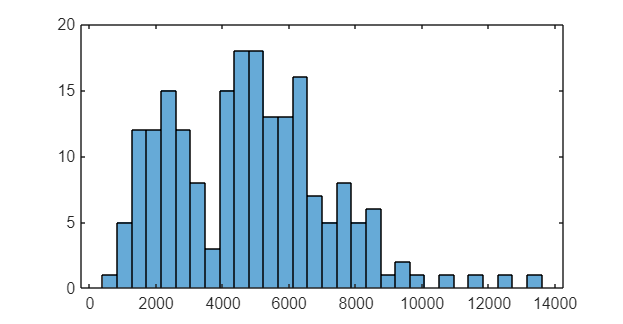

histogram(crackData.Area,30)

cutOffArea = 4000;
crackData.Risk = discretize(crackData.Area,[0,cutOffArea,inf],"categorical",["Mild","Severe "]);

dsSevere = imageDatastore(crackData.fileName(crackData.Risk == "Severe"))

dsSevere =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\Concrete Crack Images\00055.jpg';
                              ' ...\Data\Concrete Crack Images\00056.jpg';
                              ' ...\Data\Concrete Crack Images\00057.jpg'
                               ... and 128 more
                              }
                     Folders: {
                              ' ...\Data\Concrete Crack Images'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


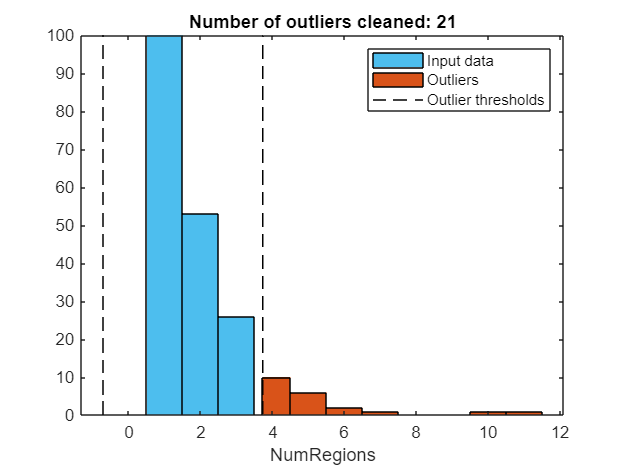

% Remove outliers
[newTable,outlierIndices,~,thresholdLow,thresholdHigh] = rmoutliers(crackData,...
    "DataVariables","NumRegions");

% Display results
figure
[~,binEdges] = histcounts(crackData.NumRegions);
binEdges = unique([binEdges thresholdLow.NumRegions thresholdHigh.NumRegions]);
binEdges = binEdges(isfinite(binEdges));
histogram(crackData.NumRegions,"BinEdges",binEdges,...
    "FaceColor",[77 190 238]/255,"FaceAlpha",1,"DisplayName","Input data")
hold on

% Plot outliers
histogram(crackData.NumRegions(outlierIndices),"BinEdges",binEdges,...
    "FaceColor",[217 83 25]/255,"FaceAlpha",1,"DisplayName","Outliers")

% Plot outlier thresholds
plot([thresholdLow.NumRegions*[1 1] NaN thresholdHigh.NumRegions*[1 1]],...
    [ylim missing ylim],"k--","DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices))
legend
xlabel("NumRegions")

clear thresholdLow thresholdHigh binEdges

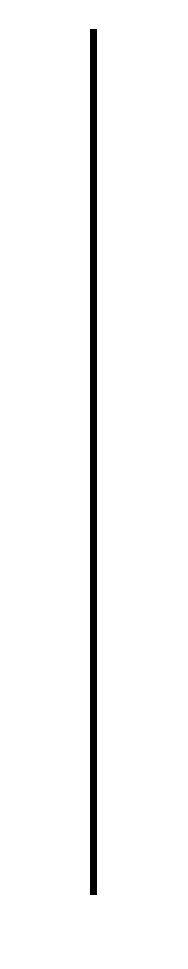

outlierImages = crackData.fileName(outlierIndices);
montage(outlierIndices,"BorderSize",1)

imgName = outlierImages(2);

img = imread(imgName)

img = 227×227×3 uint8 array
img(:,:,1) =

   152   159   157   146   144   152   155   151   152   148   144   142   143   146   149   151   155   156   158   160   161   160   160   159   156   154   151   148   148   149   151   153   151   152   154   155   155   154   153   152   152   150   148   147   148   151   154   156   149   149   149   149   149   150   151   152   151   152   154   156   155   154   152   151   157   154   150   147   145   144   144   144   143   138   138   145   147   139   133   132   137   140   143   147   149   148   147   146   148   163   168   159   155   156   145   127   129   134   131   123   128   147   161   163   157   164   163   151   141   138   138   136   134   134   135   136   137   137   138   138   144   147   150   152   154   156   160   162   151   156   160   160   157   154   154   155   151   159   160   152   149   152   147   137   120   111   108    95    95    92    78    93    86    92    77   101   135   134   136   1

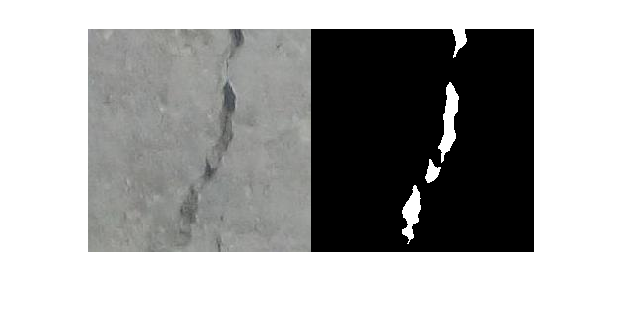

imgSeg = crackAnalysis(img);
imshowpair(img,imgSeg.BW,"montage")